# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** :**

**학번**** :**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

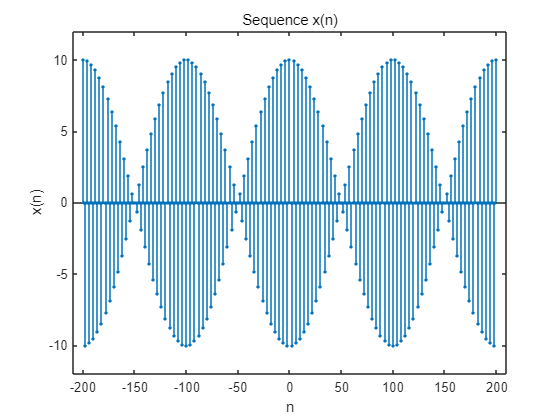

n=[-200:200];
x= 5*(cos(0.49*pi*n) + cos(0.51*pi*n));

Hf_1 = figure; 
set(Hf_1,'NumberTitle','off','Name','P0201e');
Hs = stem(n,x,'filled'); 
set(Hs,'markersize',2);
axis([min(n)-10,max(n)+10,min(x)-2,max(x)+2]);
xlabel('n'); 
ylabel('x(n)');
title('Sequence x(n)');

2) 

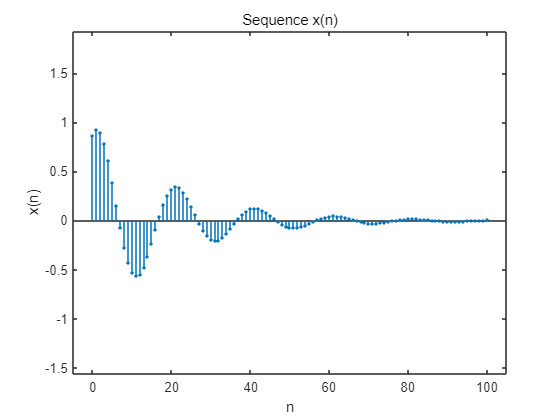

n = [0:100];
x = exp(-0.05*n).*sin(0.1*pi*n + pi/3);
Hf_1 = figure; 
Hs = stem(n,x,'filled'); 
set(Hs,'markersize',2);
axis([min(n)-5,max(n)+5,min(x)-1,max(x)+1]);
xlabel('n'); 
ylabel('x(n)');
title('Sequence x(n)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

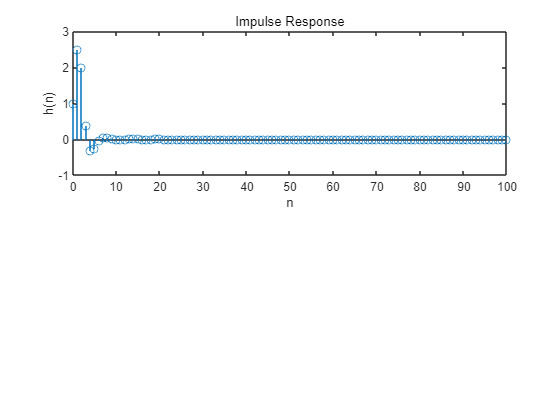

b = [1, 2, 1]; a = [1, -0.5, 0.25];
n = [0:100];
h = impz(b,a,n);
subplot(2,1,1);
stem(n, h);
title('Impulse Response');
xlabel('n');
ylabel('h(n)');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 6.5714

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

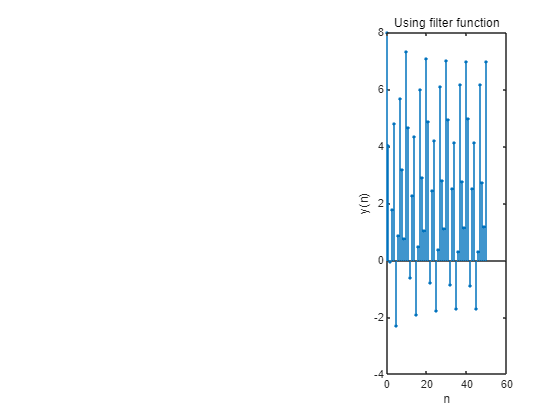

n = [0:50];
x = 5 + 3*cos(0.2*pi*n) + 4*sin(0.6*pi*n); 
h = (-0.9).^n;
Hf_1 = figure; 
y1 = filter([1],[1,0.9],x);
subplot(1,3,3);
Hs1 = stem(n,y1,'filled');
set(Hs1,'markersize',2);
title('Using filter function');
xlabel('n');
ylabel('y(n)');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

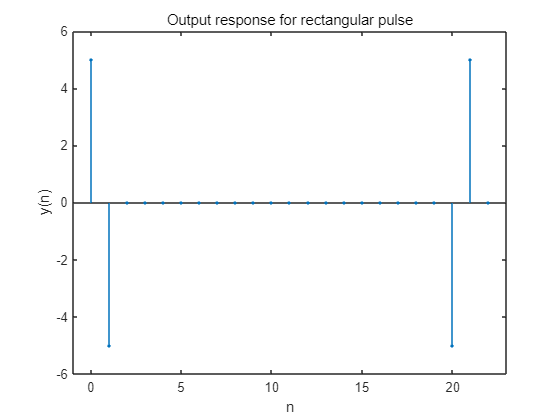

a = 1;
b = [1 -1];
n1 = 0:22;
[x11,nx11] = stepseq(0,0,22); 
[x12,nx12] = stepseq(20,0,22);
x1 = 5*(x11 - x12);
y1 = filter(b,a,x1);

Hf_1 = figure;
Hs = stem(n1,y1,'filled');
set(Hs,'markersize',2);
axis([-1,23,-6,6]);
xlabel('n');
ylabel('y(n)');
title('Output response for rectangular pulse');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

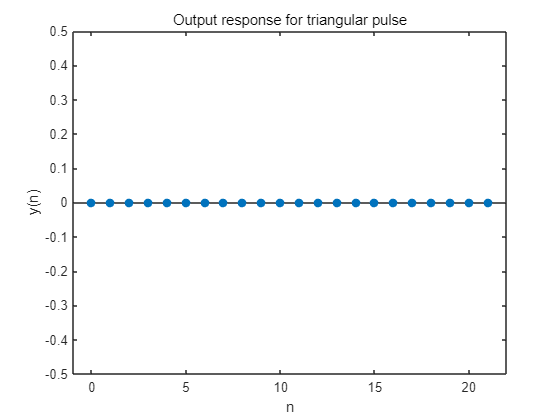

a= 1;
b = [1 -1];
n2 = 0:21;
[x11, nx11] = stepseq(0,0,21);
[x12, nx12] = stepseq(10,0,21);
[x13, nx13] = stepseq(20,0,21);
x2 = n2.*(x11 - x12) + (20 - n2).*(x12 - x13);
y2 = filter(b,a,x2);

Hf_1 = figure;
Hs = stem(n2,y2,'filled');
axis([min(n2)-1,max(n2)+1,min(y2)-0.5,max(y2) + 0.5]);
xlabel('n');
ylabel('y(n)');
title('Output response for triangular pulse');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

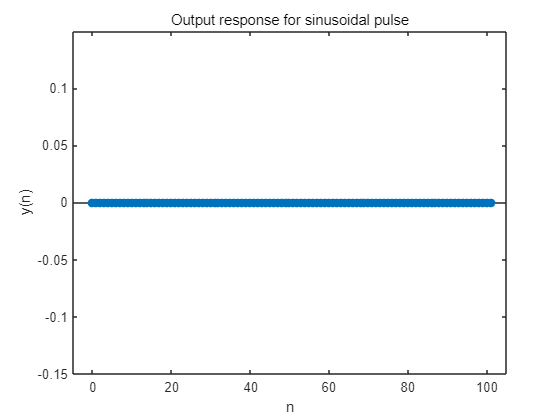

a = 1;
b = [1 -1]; 
n3 = 0:101; 
[x11,nx11] = stepseq(0,0,101);
[x12,nx12] = stepseq(100,0,101);
x13 = x11-x12;
x3 = sin(pi*n3/25).*x13;
y3 = filter(b,a,x3);

Hf_1 = figure;
Hs = stem(n3,y3,'filled');
axis([-5,105,-0.15,0.15]);
xlabel('n');
ylabel('y(n)');
title('Output response for sinusoidal pulse');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

5. (P3.17) 

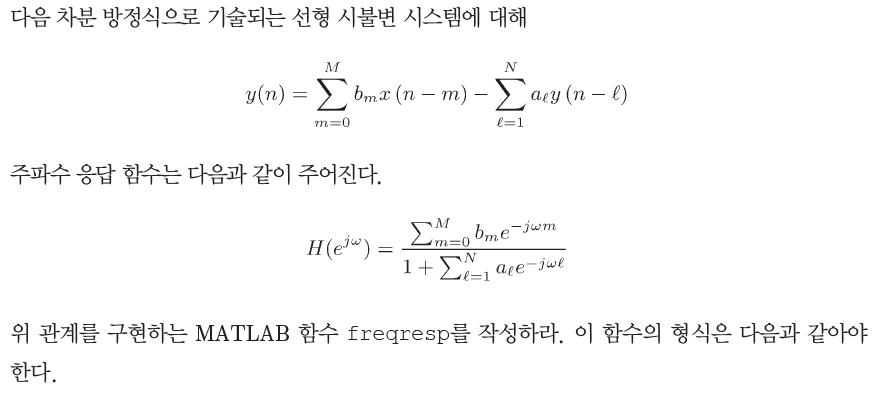

w = [-300:300]*pi/300; 
a = [1]; 
b = [0.2 0.2 0.2 0.2 0.2];
[H] = freqresp(b,a,w); 

Output argument "H" (and possibly others) not assigned a value in the execution with "HW1_학번_이름 (1)>freqresp" function.

magH = abs(H); 
phaH = angle(H)*180/pi;
Hf_1 = figure; 
subplot(2,1,1);
plot(w/pi,magH,'LineWidth',1.5); 
axis([-1 1 0 1.2]);
xlabel('\omega / \pi'); 
ylabel('|H|');
title(['Magnitude response']);
subplot(2,1,2); plot(w/pi,phaH,'LineWidth',1.5); axis([-1 1 -220 220]);
xlabel('\omega / \pi'); ylabel('Degrees');
title('Phase Response ');

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

function [x,n] = stepseq(n0,n1,n2)
n = [n1:n2];
x = [(n-n0) == 0];
end

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

end